# Working with Text and Categories

Previously, you worked with datetime and duration data. In this reading, you'll look at text and categories of data and the available data types for them. You'll create or import text and work with it to improve your visualizations or group data into categories for further analysis.

To get started, import the table of pizza orders by running the live script you generated using the Import Tool.

importOrders

## Text Data

In this section, you'll work with the text variable `Description` to learn which toppings were ordered most frequently. Each row of this variable contains a string with the pizza order. These include the order number, pizza number, toppings, and additional order specifications such as "heavy cheese" and "light sauce". For example, here is the 31st element.

orders.Description(31)

### Visualizing Text Data

Word clouds help you understand the relative frequency of different terms in your text data. To see which toppings were ordered most frequently, create a word cloud.

First, insert a **Create Plot** task in the empty code box below.

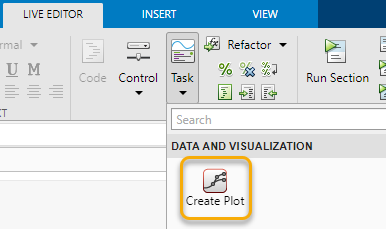

Then, under **Select Data **in the task, select the `orders` table and the variable `Description.` Next, select the visualization` wordcloud`.

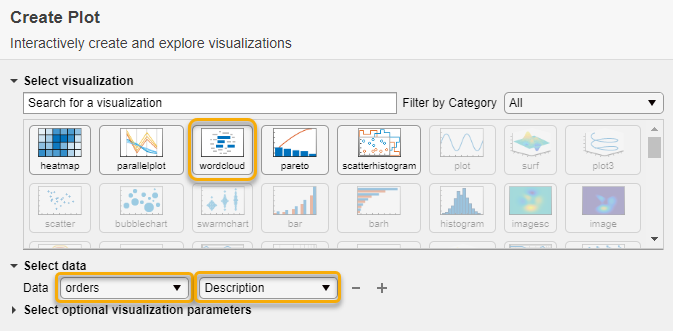


% insert 'create plot' task here


Click the options menu in the top right of the live task and select **Controls and Code** to see the generated code.

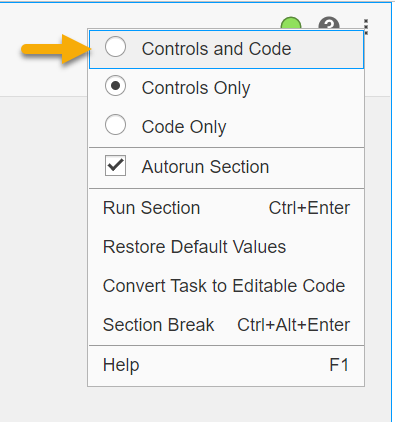

In this case, the live task used the function `wordcloud` to create the visualization.

### Editing Text Data

**Extracting Text**

In the word cloud above, the words "Order" and "Pizza" are the largest, indicating that these are the most frequent terms in the data.

However, since the goal is to see which *toppings* were ordered most frequently, the words "Order" and "Pizza" are redundant. For example, if you look at some of the entries in `Description` by running the following line of code,

orders.Description

you'll see that the important information comes after the colon and the space which follows the colon.

So, use the function `extractAfter` to extract the text which occurs after the colon (:) in each row. Save the output as a new table variable, `ToppingsList`.

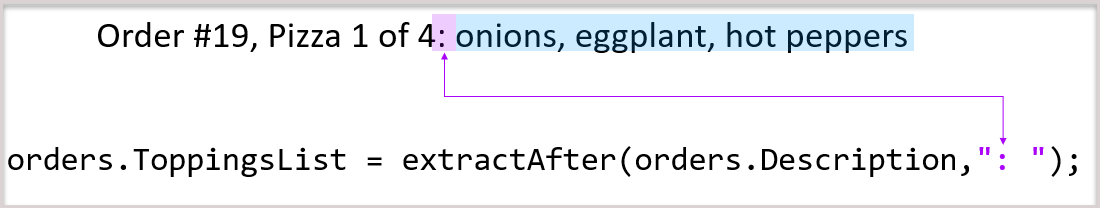

orders.ToppingsList = extractAfter(orders.Description,": ");

This new table variable only contains what occurs after the colon in each row of` Description`. Here's the 31st element of` ToppingsList`, for example.

orders.ToppingsList(31)

**Erasing Text**

Phrases like "heavy sauce" and "light cheese" still contribute to the word cloud. These order specifications are each two words long, so they are treated as separate terms. 

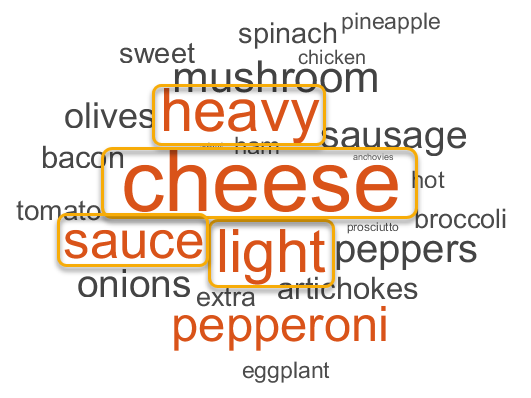

Additionally, these phrases don't help you understand which toppings were ordered most frequently. It would be best to erase these phrases from` ToppingsList`.

The following string array contains the phrases to be erased from `ToppingsList`.

extraPhrases = ["heavy sauce","light sauce","heavy cheese","light cheese","extra"];

Use the function `erase` to erase these phrases from `ToppingsList`.

orders.ToppingsList = erase(orders.ToppingsList,extraPhrases);

This variable no longer contains phrases like "heavy sauce" and "light cheese". Here's the 31st element to see the difference from before.

orders.ToppingsList(31)

**Replacing Text**

The phrases "sweet peppers" and "hot peppers" are each two words long, so "sweet", "hot", and "peppers" are all treated as separate terms in the word cloud.

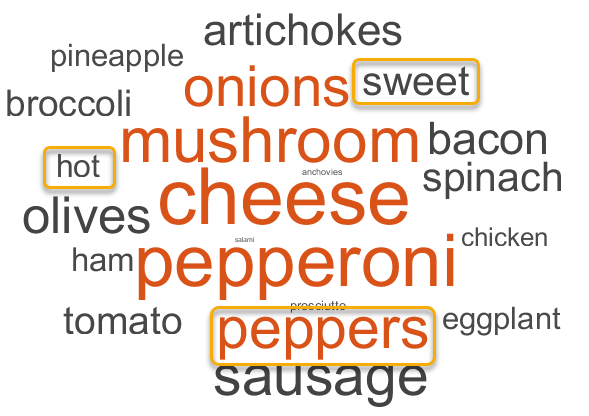

Unlike "heavy cheese" and "light sauce", these phrases *do *help capture which toppings were ordered. It would be best to keep these phrases but to collapse them each into a single term. 

The array defined below contains the strings to be changed.

oldStrings = ["hot peppers" "sweet peppers"];

And the following array contains the strings with which to replace the old ones.

newStrings = ["hot_peppers" "sweet_peppers"];

Use the function `replace` to replace the old strings with the new ones.

orders.ToppingsList = replace(orders.ToppingsList, oldStrings, newStrings);

Finally, make a new word cloud to see the most common terms in the cleaned toppings list.

wordcloud(orders.ToppingsList)

As expected, the words "Order" and "Pizza" no longer contribute to this word cloud. Neither do phrases like "heavy sauce" and "light cheese". Additionally, the terms "sweet_peppers" and "hot_peppers" informatively contribute to this word cloud. 

Cheese pizzas are very popular! And it looks like pepperoni, mushroom, sausage, and onion are some of the most popular toppings.

### Practice with Text

You just saw the functions` extractAfter`, `erase`, and `replace`. There are plenty more functions to try out, like `extractBefore`, `eraseBetween`, `insertBefore`, and `insertAfter`.

Give `extractBefore` a try. Create a new table variable called `OrderPizzaNumber` by extracting the text from *before* the colon in each row of the variable,` Description`.

Check your work by looking at the 31st element of` OrderPizzaNumber`. It should be a string that reads `"Order #14, Pizza 1 of 3"`.

## Categorical Data

The table variable `CancelReason` contains the different reasons for canceled orders. The values appear to contain letters:

orders.CancelReason

However, `CancelReason` is not a text variable. Rather, it is a categorical variable because it consists of a set of discrete categories.

When you scroll through the values, you'll notice that many rows are of the category "NC". Use the function `Categories` to see all of the available categories in this variable.

categories(orders.CancelReason)

### Renaming Categories

Each category corresponds to a specific reason an order was canceled.

- “NC” is “Not Canceled”

- “86” is “Ingredient Shortage”

- “LW” is “Long Wait”

- “U” is “Unknown”

The meaning of these names requires insight, and they are rather hard to read. Change the category names so that they are more descriptive.

The array below contains the old category names.

oldCategories = ["NC","86","LW","U"];

The next array contains the new category names.

newCategories = ["Not Canceled","Ingredient Shortage","Long Wait","Unknown"];

Create a new table variable, `CancelReasonLong`, which contains these more descriptive category names. Use the function `renamecats` to accomplish this task.

orders.CancelReasonLong = renamecats(orders.CancelReason,oldCategories,newCategories);

Now, use `histogram` to see how many elements fall under each of the four categories.

histogram(orders.CancelReasonLong)
xlabel("CancelReasonLong")
ylabel("Count")

### Removing Categories

The histogram above shows there are a small number of pizzas that were canceled for an unknown reason. What if you wanted to disregard these data points? How can you remove this category and focus on the remaining orders?

Use the function `removecats` to remove one or more categories from a categorical variable. The 2nd argument should have the names of categories to remove.  

orders.CancelReasonLong = removecats(orders.CancelReasonLong,"Unknown");

Now the variable only has three categories. The orders previously labeled `"Unknown"` are now labeled `<undefined>` and will not appear in visualizations. Check this yourself by creating another histogram. 

histogram(orders.CancelReasonLong)
xlabel("CancelReasonLong")
ylabel("Count")

### Creating Categorical Variables

Let's say you import a vector of integers that denote different types of fruit:

fruitvalues = [1; 3; 2; 1; 1; 2; 3]

Use the function `categorical` to convert this data. The second argument is the possible category values (in this case, the integers 1 to 3), and the third argument is the corresponding list of names.

fruits = categorical(fruitvalues,[1 2 3],["Apples","Bananas","Oranges"])

### Practice with Categorical Data

Besides renaming and removing categories, another common task is merging categories. Try merging the "Bananas" and "Oranges" categories in the variable `fruits` into a single one named "Not apples". 

Use the function [`mergecats`](https://www.mathworks.com/help/matlab/ref/categorical.mergecats.html) to merge the two variables. Store the result in a new variable named `appleLabel`.

## The Difference Between the Text Data Types `String` and `Char`

Each entry in the Description variable is a type of text of data called a `string`. These are always enclosed in double quotes. Here is an example of a single string.

myString = "sweet peppers"

You've also seen text data enclosed in single quotes. This is a different kind of data type called a `char`, which is short for "character."

myChar = 'sweet peppers'

Most MATLAB functions will accept either `string` or `char` variables, but there are some key differences between the two data types.

- A `char` variable contains one or more characters

            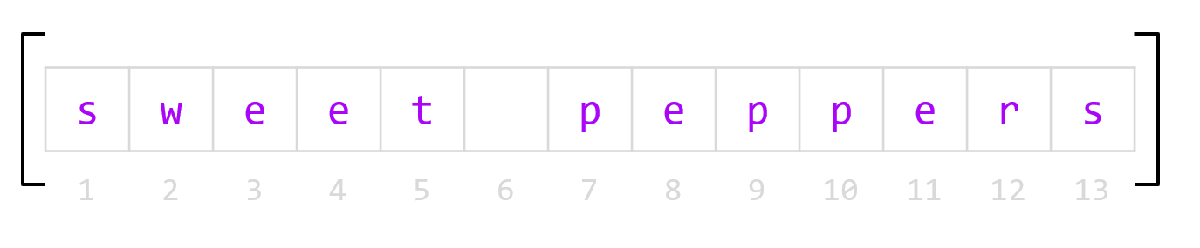

- A `string` variable contains one or more strings

            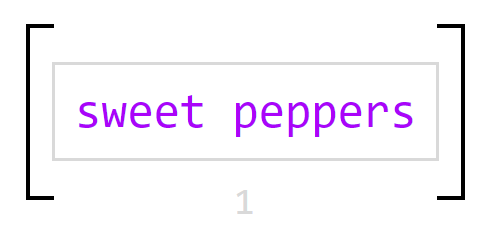

The easiest way to see this difference is with the function `length`. For `myChar`, the function returns a value of 13 because `myChar` has 13 characters. For m`yString`, the function returns 1 because `myString` only contains one string. For a text variable like `orders.Description`, the function returns a number greater than 1 because it is a vector of strings.

length(myChar)
length(myString)
length(orders.Description)

Why are there two different text data types? Historically, the only way to store text data was in `char` variables. Now, they are less widely used but are still useful when you need to manipulate individual characters. The `string` data type is newer and generally more useful, especially for organizing multiple pieces of text data like the pizza descriptions.

### Concatenating Text Data

You've seen how to join numbers together into a vector. You can do the same with text data but with different methods for each data type.

[myChar ', onions']

This line concatenated the characters `', onions'` onto the variable `myChar`, creating a longer character vector. This same operation has a different result with strings

[myString ", onions"]

Notice the output is a 1x2 `string` vector with two separate elements. The two strings were not concatenated into a single element. Instead, use the addition sign `+` to concatenate the two strings into a single string.

myString + ", onions"

### Converting Text Data

If you need to convert one text type to another, use the functions `char` and `string`.

char(myString)
string(myChar)

The `string` function can also be used to convert numbers to strings, but not the `char` function.

string(pi)

Conversely, use the function [`double`](https://www.mathworks.com/help/matlab/ref/double.html) to convert a string variable to a numeric variable, 

double("3.14159265359")

### Practice with String and Char Variables

Try creating two text variables with different pizza toppings, one as a `string` variable and the other as a `char` variable. Then, try concatenating them together with the methods shown above. What was the result of each method? 

In this reading, you completed various tasks with different types of text and categorical data. With each of these data types, you created new variables, modified existing ones, and created great visualizations, like the word clouds. Later, you'll use this knowledge about the non-numeric data types of both readings to do further analysis on your data.

*Copyright 2021 The MathWorks, Inc.*